# Question 1

Read input file:

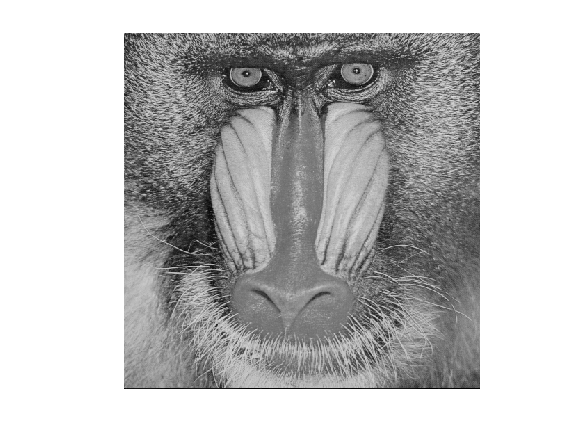

im = imread("/MATLAB Drive/images/mandrill.tif");
imshow(im)

Create a binary mask containing eyes:

yi = [91,91,417,417];
xi = [30,110,110,30];
roi = roipoly(im,yi,xi);

## Low pass filters:

Average:

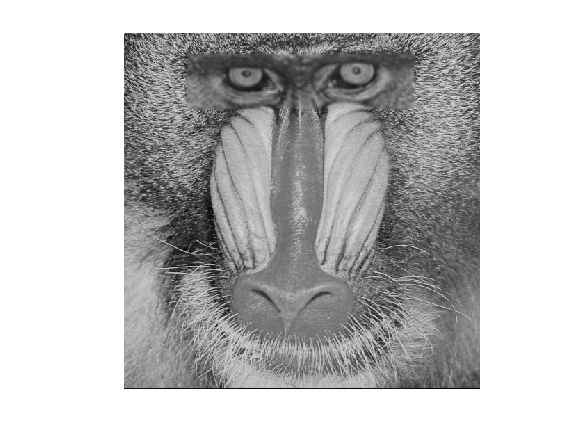

a = fspecial('average',5);
ima = roifilt2(a,im,roi);
imshow(ima)

Gaussian:

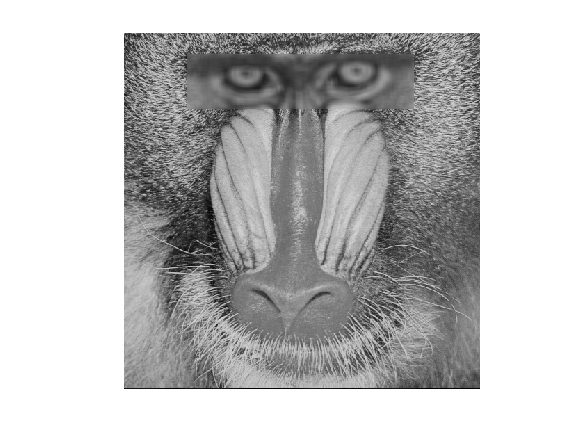

g = fspecial('gaussian',10,50);
img = roifilt2(g,im,roi);
imshow(img)

## High pass filters:

Lapacian:

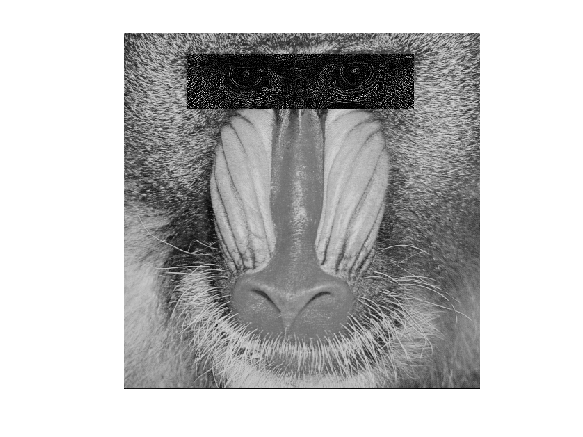

l = fspecial('laplacian',0.2);
iml = roifilt2(l,im,roi);
imshow(iml)

Prewitt:

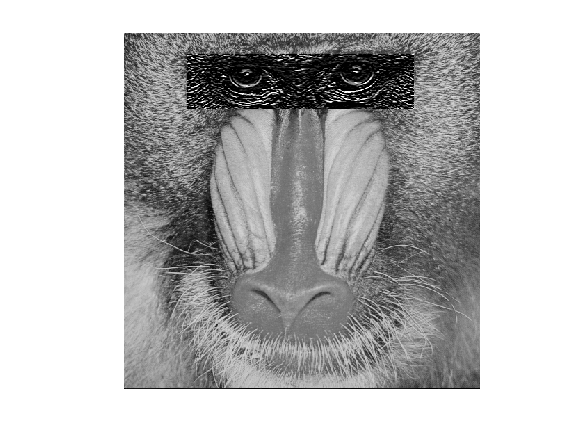

p = fspecial('prewitt');
imp = roifilt2(p,im,roi);
imshow(imp)